[sectn] = sectn_rectangularSolid(a, b)

sectn_rectangularSolid(a, b) computes the beam section properties for a beam of rectangular solid cross section.

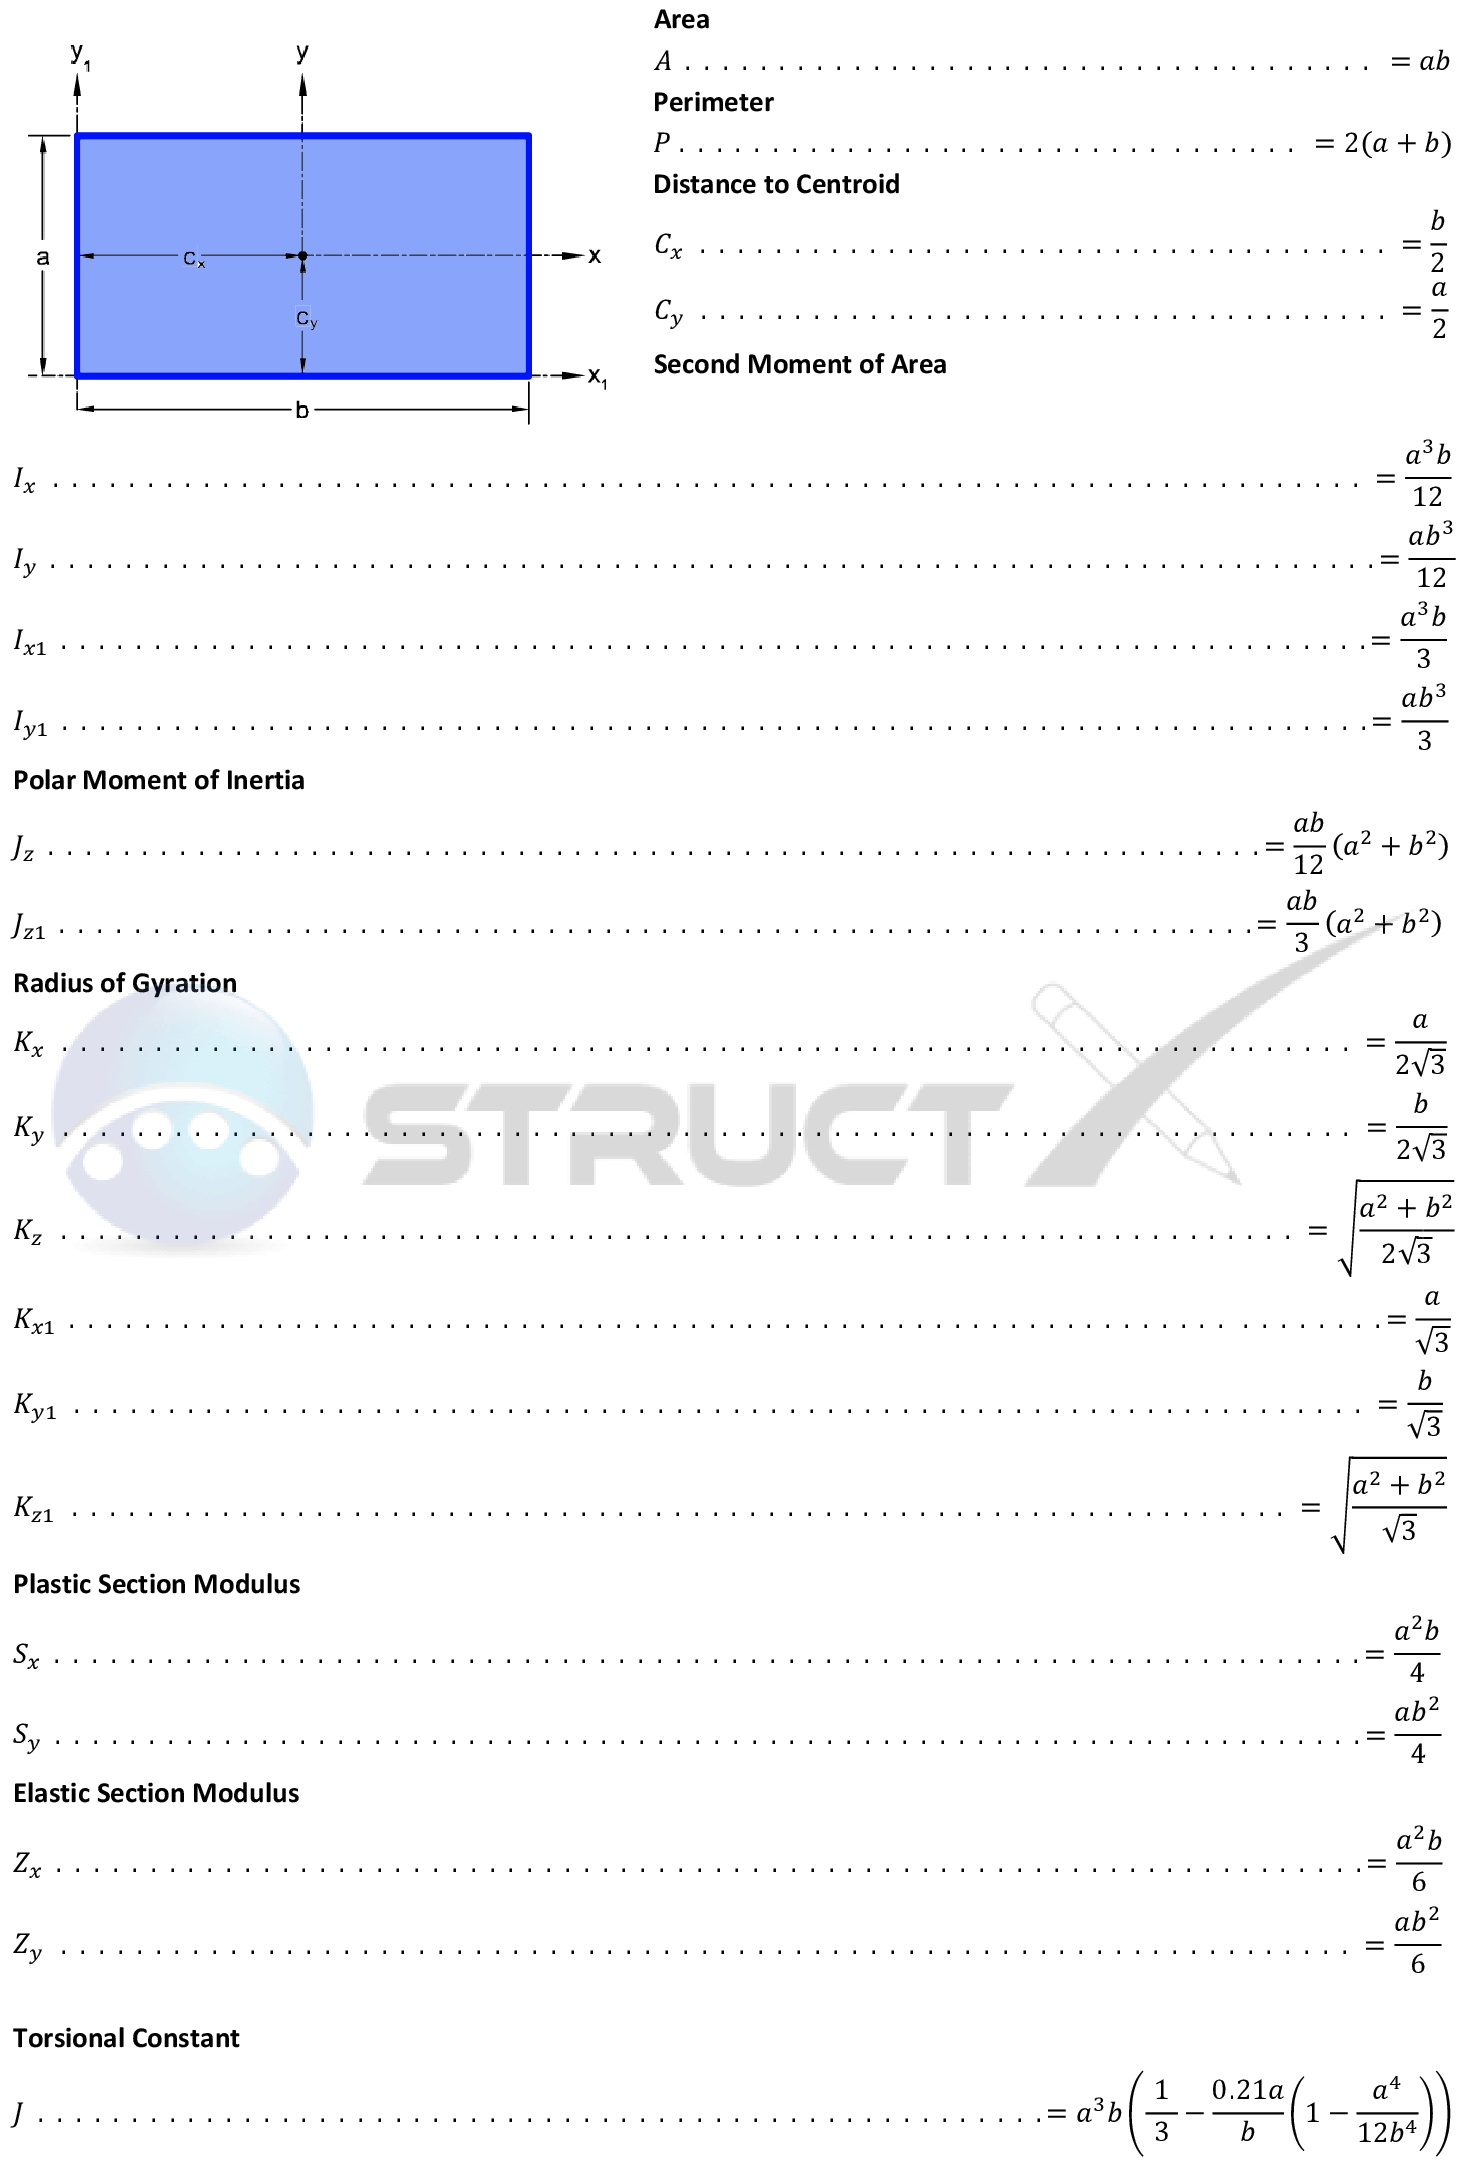

### Notation:

- A = Geometric Area, in2 or mm2

- C = Distance to Centroid, in or mm

- I = Second moment of area, in4 or mm4

- Ji = Polar Moment of Inertia, in4 or mm4, where i is x, y or z

- K = Radius of Gyration, in or mm

- P = Perimeter of shape, in or mm

- Z = Elastic Section Modulus, in3 or mm3

### Calling Sequence:

- [sectn] = sectn_rectangularSolid(a, b)

#### Inputs:

- a - rectangle outside height

- b - rectangle outside base

#### Outputs:

- sectn - sectn data structure with updated section properties

### Reference:

- https://structx.com/Shape_Formulas_024.html

function [sectn] = sectn_rectangularSolid(b, h)
sectn.type = 'rectSolid';           % section type
sectn.A = a*b;                      % cross-section area
sectn.P = 2*(a+b);                  % perimeter
sectn.C1 = a/2;                     % distance to centroid, axis-1
sectn.C2 = b/2;                     % distance to centroid, axis-2
sectn.I1 = (1/12)*a^3*b;            % area moment of inertia, axis-1
sectn.I2 = (1/12)*a*b^3;            % area moment of inertia, axis-2
sectn.Jz = sectn.I1 + sectn.I2;     % polar moment of inertia
sectn.Z1 = a^2*b/6;                 % section modulus, axis-1
sectn.Z2 = a*b^2/6;                 % section modulus, axis-2
sectn.K1 = sectn.I1/sectn.C1;       % radius of gyration, axis-1
sectn.K2 = sectn.I2/sectn.C2;       % radius of gyration, axis-2
sectn.J  = a^3*b*((1/3)-((0.21-a)/b)*(1-(a^4/(12*b^4))));   % torsional constant
end